# mdot deltaP

Script for importing data from the following text file:

Auto-generated by MATLAB on 29-Dec-2022 18:06:40

## Set up the Import Options and import the data

clear
opts = delimitedTextImportOptions("NumVariables", 31);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["var_min_air_gap", "var_c_r", "var_c_a", "var_h_C", "var_r_Cout", "var_D_w", "var_t_cfr", "var_t_cfa", "var_t_mba", "var_t_mta", "var_r_A", "var_r_cham", "var_h_cham", "var_t_shell", "var_PR", "var_CSF", "var_h_air", "var_mu", "var_mu0", "var_CWCC", "var_erc", "Nturns", "P", "Ks", "orifice_opening_t", "orifice_closing_t", "total_flow", "total_power", "weight", "deltaP", "mdot","chamber_rho","nozzle_A"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
designoptions = readtable("C:\Users\kutla\Documents\GitHub\thesis\test_design3-mdot_deltaP.csv", opts)

designoptions = 10×33 table
    var_min_air_gap    var_c_r    var_c_a    var_h_C    var_r_Cout    var_D_w    var_t_cfr    var_t_cfa    var_t_mba    var_t_mta    var_r_A    var_r_cham    var_h_cham    var_t_shell    var_PR    var_CSF    var_h_air    var_mu     var_mu0      var_CWCC    var_erc     Nturns        P         Ks      orifice_opening_t    orifice_closing_t    total_flow    total_power    weight       deltaP         mdot       chamber_rho     <

## Clear temporary variables

clear opts

size(designoptions)

ans =     10    33


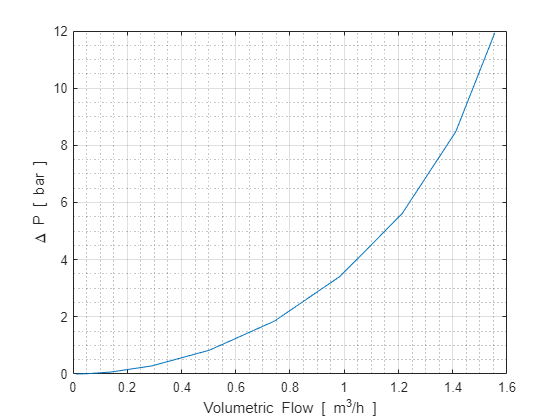


figure
plot(designoptions.mdot./designoptions.chamber_rho*3600,Pa_to_B(designoptions.deltaP))
xlabel('Volumetric Flow [ m^3/h ]'),ylabel('\Delta P [ bar ]'),grid on, grid minor

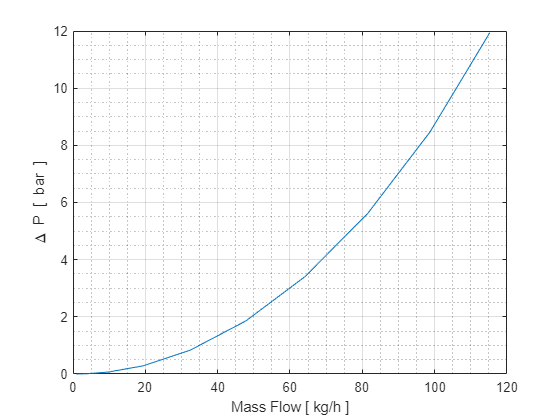


figure
plot(designoptions.mdot*3600,Pa_to_B(designoptions.deltaP))
xlabel('Mass Flow [ kg/h ]'),ylabel('\Delta P [ bar ]'),grid on, grid minor